clf;clear
load('G:\Users\iCalculate\Download\IDS_COLORCHECK_1020-1223.mat');
Xmin = 490;
Xmax = 704;
Ymin = 600;
Ymax = 942;
lambda = 400:400/30:800;
WL = 500:1:800;
rad = rad(Xmin:Xmax,Ymin:Ymax,:);
RAD = zeros(Xmax-Xmin+1,Ymax-Ymin+1,length(WL));
rgb = rgb(Xmin:Xmax,Ymin:Ymax,:);
for i = 1:Xmax-Xmin+1
    for j = 1:Ymax-Ymin+1
        s = reshape(rad(i,j,:),1,31);
        S = interp1(lambda, s, WL,"pchip");
        RAD(i,j,:) = S;
    end
end


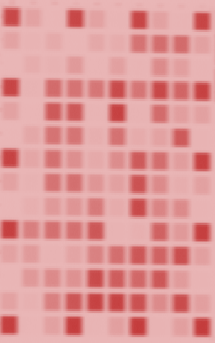

clf;
figure(2);
HSV = hsv;

MAX = max(max(max(rad)));
for i=1:30:301
    color = HSV(ceil((302-i)/300*190),:)*0.7;
    Grad = 0.1:0.9/255:1;
    CM = ones(256,3)-repmat([1,1,1]-color,256,1).*repmat(Grad',1,3);
    %subplot(4,3,(i+29)/30);
    normImg = RAD(:,:,i)/MAX*256;
    [x,y,z] = size(normImg);
    imshow(normImg,CM,'border','tight','initialmagnification','fit');
    axis normal;
    set (gcf,'Position',[0,0,x,y]);
    saveas(2, ['save',num2str(i+499),'.jpg']);
%     view([0.600 90.000]);
end

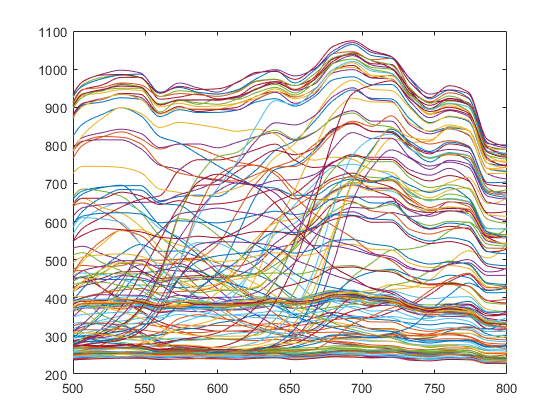

Xlist = ceil(12:(206-12)/13:206);
Ylist = ceil(19:(324-19)/9:324);
figure(3)

for x = Xlist
    for y = Ylist
        plot(WL, reshape(RAD(x,y,:),301,1));
        hold on;
    end
end

clf;
AbsList = zeros(301,8);
Yaim = 11*ones(1,8)-[2,3,7,9,2,4,4,3];
Xaim = 15*ones(1,8)-[2,9,2,5,5,5,13,14];
for k=1:8
    Abs = reshape(RAD(Xlist(Xaim(k)),Ylist(Yaim(k)),:),301,1);
    AbsList(:,k) = Abs;
end

